m=0.05*ones(2,1);
k=0.01*ones(3,1);
xci=0.025;
xv0=[xci*0.5;xci;0;0];
M=[-(k(1)+k(2))/m(1),k(2)/m(1);
    k(2)/m(2),-(k(2)+k(3))/m(2)]

M =   -0.400000000000000   0.200000000000000
   0.200000000000000  -0.400000000000000


Md=[zeros(2,2),eye(2);M,zeros(2,2)]

Md =                    0                   0   1.000000000000000                   0
                   0                   0                   0   1.000000000000000
  -0.400000000000000   0.200000000000000                   0                   0
   0.200000000000000  -0.400000000000000                   0                   0


f=@ (t,xv) Md*xv;
t0=0;
h=0.001;
tf=20;
[t,xv]=ivps(f,t0,xv0,h,tf,'trapezoide')

t =                    0   0.001000000000000   0.002000000000000   0.003000000000000   0.004000000000000   0.005000000000000   0.006000000000000   0.007000000000000   0.008000000000000   0.009000000000000   0.010000000000000   0.011000000000000   0.012000000000000   0.013000000000000   0.014000000000000   0.015000000000000   0.016000000000000   0.017000000000000   0.018000000000000   0.019000000000000   0.020000000000000   0.021000000000000   0.022000000000000   0.023000000000000   0.024000000000000   0.025000000000000   0.026000000000000   0.027000000000000   0.028000000000000   0.029000000000000   0.030000000000000   0.031000000000000   0.032000000000000   0.033000000000000   0.034000000000000   0.035000000000000   0.036000000000000   0.037000000000000   0.038000000000000   0.039000000000000   0.040000000000000   0.041000000000000   0.042000000000000   0.043000000000000   0.044000000000000   0.045000000000000   0.046000000000000   0.047000000000000   0.048000000000000   0.04900000000

xv =    0.012500000000000   0.012500000000000   0.012500000000000   0.012499999999997   0.012499999999987   0.012499999999966   0.012499999999927   0.012499999999861   0.012499999999759   0.012499999999609   0.012499999999398   0.012499999999113   0.012499999998738   0.012499999998255   0.012499999997645   0.012499999996889   0.012499999995965   0.012499999994849   0.012499999993517   0.012499999991942   0.012499999990096   0.012499999987951   0.012499999985476   0.012499999982638   0.012499999979404   0.012499999975738   0.012499999971604   0.012499999966963   0.012499999961776   0.012499999956001   0.012499999949596   0.012499999942516   0.012499999934716   0.012499999926148   0.012499999916764   0.012499999906514   0.012499999895345   0.012499999883204   0.012499999870038   0.012499999855789   0.012499999840399   0.012499999823810   0.012499999805961   0.012499999786790   0.012499999766232   0.012499999744222   0.012499999720695   0.012499999695581   0.012499999668811   0.0124999996

x=xv(1:2,:);
v=xv(3:4,:)

v =                    0  -0.000000000000000  -0.000000001500000  -0.000000005999999  -0.000000014999994  -0.000000029999978  -0.000000052499939  -0.000000083999859  -0.000000125999714  -0.000000179999471  -0.000000247499086  -0.000000329998505  -0.000000428997664  -0.000000545996482  -0.000000682494868  -0.000000839992711  -0.000001019989886  -0.000001223986250  -0.000001453481640  -0.000001709975872  -0.000001994968741  -0.000002309960020  -0.000002656449458  -0.000003035936776  -0.000003449921672  -0.000003899903815  -0.000004387382845  -0.000004913858373  -0.000005480829978  -0.000006089797206  -0.000006742259570  -0.000007439716549  -0.000008183667586  -0.000008975612085  -0.000009817049413  -0.000010709478897  -0.000011654399823  -0.000012653311437  -0.000013707712939  -0.000014819103485  -0.000015988982187  -0.000017218848110  -0.000018510200269  -0.000019864537633  -0.000021283359117  -0.000022768163587  -0.000024320449856  -0.000025941716681  -0.000027633462766  -0.00002939718

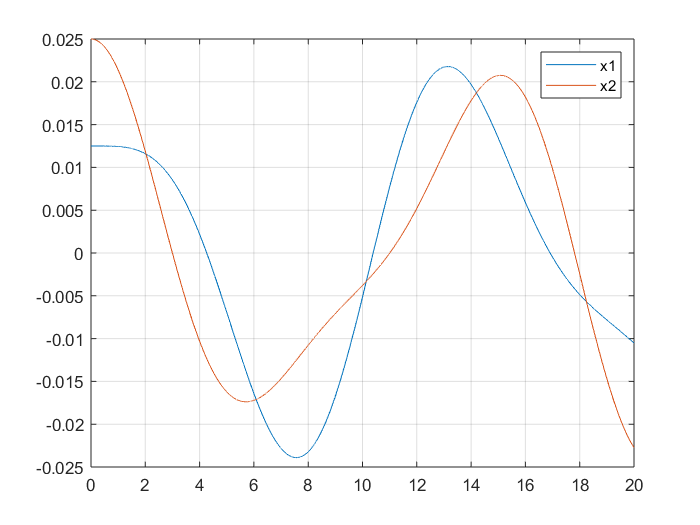

plot(t,x);
grid on;
legend('x1','x2');

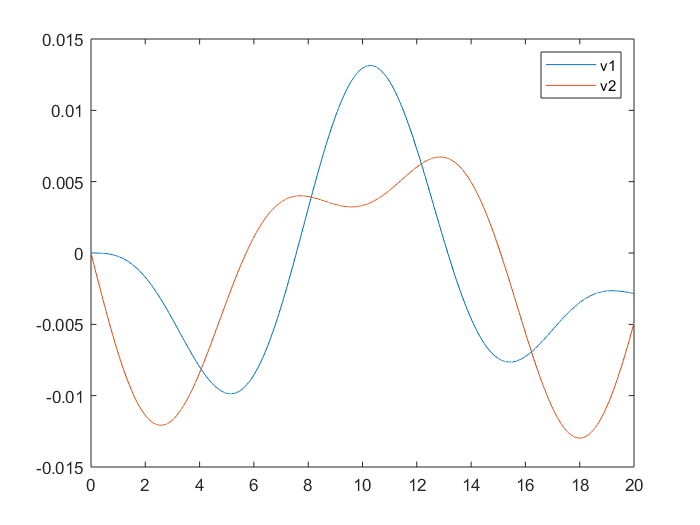

plot(t,v);
legend('v1','v2');

lambda=eig(M)

lambda =   -0.600000000000000
  -0.200000000000000


a=sqrt(lambda)

a =   0.000000000000000 + 0.774596669241483i
  0.000000000000000 + 0.447213595499958i


w=imag(a)

w =    0.774596669241483
   0.447213595499958


periodo=(2*pi)./w

periodo =    8.111557351947223
  14.049629462081453
